# `Activity 8`

## `Formant Estimation with LPC Coefficients`

[data, Fs] = audioread('sarigamapa.wav');
data = data(:,1);

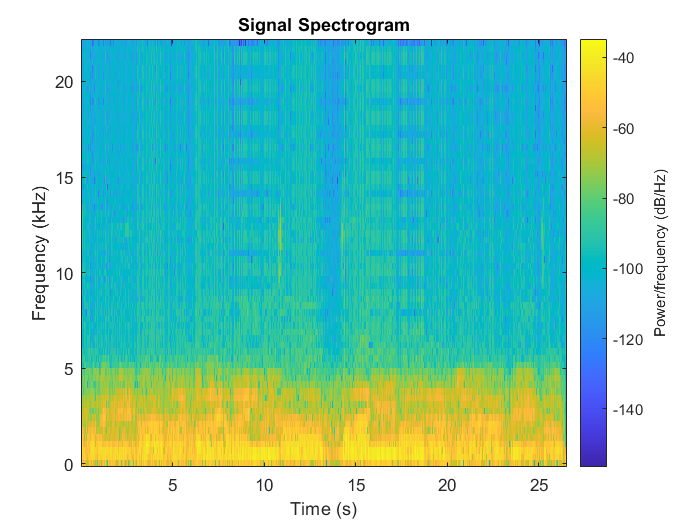

segmentlen = 100;
noverlap = 90;
NFFT = 128;

spectrogram(data,segmentlen,noverlap,NFFT,Fs,'yaxis')
title('Signal Spectrogram')

dt = 1/Fs;
I0 = round(0.1/dt);
Iend = round(0.25/dt);
x = data(I0:Iend);
x1 = x.*hamming(length(x));

Apply a pre-emphasis filter. The pre-emphasis filter is a highpass all-pole (AR(1)) filter.

preemph = [1 0.63];
x1 = filter(1,preemph,x1);
A = lpc(x1,8);
rts = roots(A)

rts =   -0.5793 + 0.3562i
  -0.5793 - 0.3562i
  -0.1117 + 0.8102i
  -0.1117 - 0.8102i
   0.8231 + 0.3814i
   0.8231 - 0.3814i
   0.9630 + 0.1123i
   0.9630 - 0.1123i


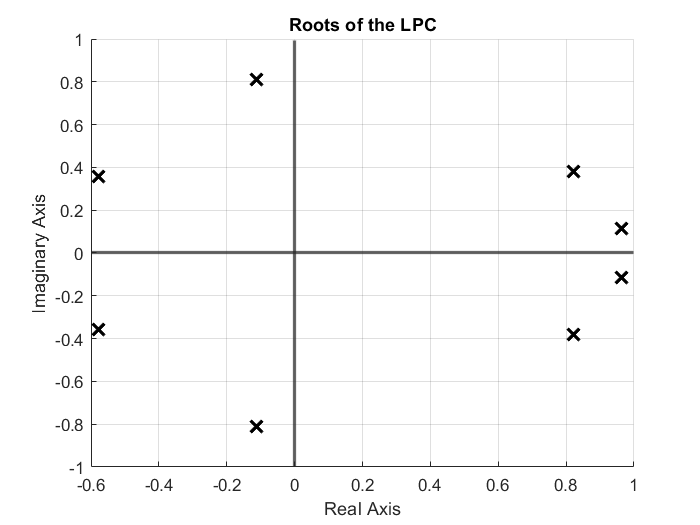

real_z1 = real(rts);
imag_z1 = imag(rts);

figure()
scatter(real_z1,imag_z1,100,'black','Marker',"x",'LineWidth',2)
xline(0,'LineWidth',2);
yline(0,'LineWidth',2);
grid on
xlabel('Real Axis')
ylabel('Imaginary Axis')
title('Roots of the LPC')

rts = rts(imag(rts)>=0);
angz = atan2(imag(rts),real(rts));

[frqs,indices] = sort(angz.*(Fs/(2*pi)));
bw = -1/2*(Fs/(2*pi))*log(abs(rts(indices)));

Use the criterion that formant frequencies should be greater than 90 Hz with bandwidths less than 400 Hz to determine the formants.

nn = 1;
for kk = 1:length(frqs)
    if (frqs(kk) > 90 && bw(kk) <400)
        formants(nn) = frqs(kk);
        nn = nn+1;
    end
end

disp(formants)

ans = 1×2 uint64 row vector
    815   3046


#### `Spectrum`

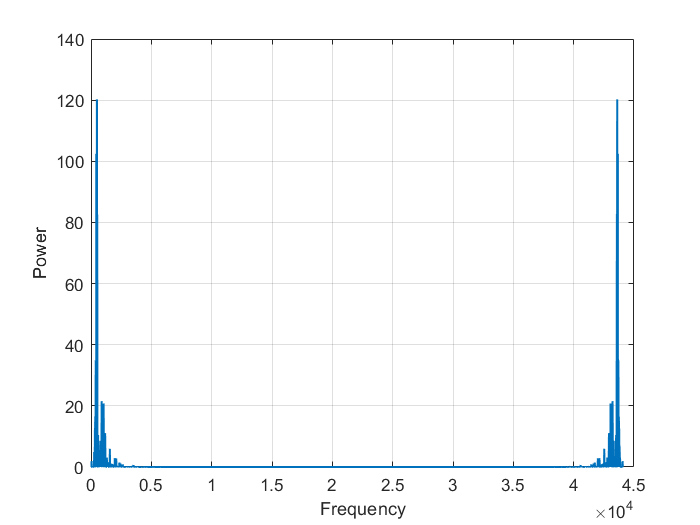

n = length(data);       % number of samples
y = fft(data);
f = (0:n-1)*(Fs/n);     % frequency range
power = abs(y).^2/n;
plot(f,power,'LineWidth',1.2);
xlabel('Frequency');
ylabel('Power');
grid on